clc 
clear
close all

# System Dynamic 

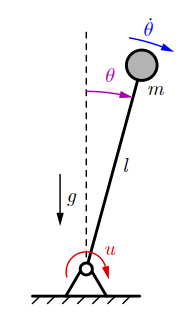

## Inverted Pendulum dynamic equation: 

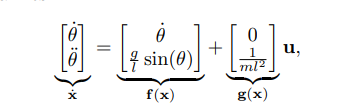

## `System Parameter`

g = 9.81; % acceleration due to gravity (m/s^2)
l = 1.0;  % length of the pendulum (m)
m = 1.0;  % mass of the pendulum (kg)

## State variables

syms  theta theta_dot
x = [theta theta_dot]

$$x = \left(\begin{array}{cc} \theta & \dot{\theta } \end{array}\right)$$

## Feasible Area

% Parameters for visualization
u_max = 3;       % Maximum control input
u_range = 4;     % Range for all possible inputs

% Create figure for control input set U
figure;
hold on;
title('Control Input Set');
xlabel('u');

% Plot feasible control input set as a line
line([-u_max, u_max], [0, 0], 'Color', 'g', 'LineWidth', 6, 'DisplayName', 'Feasible Set');
text(0, 0, 'Feasible Set', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');

% Plot larger range for all possible inputs as a dashed line
line([-u_range, u_range], [0, 0], 'Color', 'r', 'LineStyle', '--', 'LineWidth', 2, 'DisplayName', 'All Possible Inputs');

% Adjust the plot limits and aesthetics
xlim([-u_range-1, u_range+1]);
xticks([-4 -3 -2 -1 0 1 2 3 4])
ylim([-1, 2]);
set(gca, 'YTick', []); % Remove y-axis ticks
set(gca, 'YColor', 'none'); % Remove y-axis line
legend('show');
hold off;

% Visualization of the feasible set
theta_max = 0.3;       % Maximum angle (rad)
theta_dot_max = 0.6;   % Maximum angular velocity (rad/s)

% Create figure for feasible set visualization
figure;
hold on;
title('Feasible Set for State Variables', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('$\theta$ (rad)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\dot{\theta}$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 14);

% Plot feasible region
x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
fill(x1, x2, 'g', 'FaceAlpha', 0.3);

% Plot boundaries
line([-theta_max, -theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([theta_max, theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [-theta_dot_max, -theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);

text(0, 0, 'Feasible Set', 'HorizontalAlignment', 'center', 'Interpreter', 'latex', 'FontSize', 14);

% Set plot limits
xlim([-0.4, 0.4]);
ylim([-0.7, 0.7]);
hold off;

## Desired Controller (Policy)

% Initial conditions
theta0 = 0.1; % initial angle (rad)
theta_dot0 = 0; % initial angular velocity (rad/s)
x0 = [theta0; theta_dot0];

% Time span
tspan = [0 15];

% Solve the differential equation
[t, x] = ode45(@(t, x) pendulum_dynamics(t, x, g, l, m, @(t, x) control_input(t, x, g, l, m)), tspan, x0);

% Plot the results
figure;
subplot(3, 1, 1);
plot(t, x(:, 1), 'LineWidth', 2);
title('Pendulum Angle \theta(t)');
xlabel('Time (s)');
ylabel('\theta (rad)');
grid on;

subplot(3, 1, 2);
plot(t, x(:, 2), 'LineWidth', 2);
title('Pendulum Angular Velocity \theta\_dot(t)');
xlabel('Time (s)');
ylabel('\theta\_dot (rad/s)');
grid on;

% Calculate and plot the control input over time
u_vals = arrayfun(@(ti) control_input(ti, x(find(t==ti),:)', g, l, m), t);
subplot(3, 1, 3);
plot(t, u_vals, 'LineWidth', 2);
title('Control Input u_{des}(t)');
xlabel('Time (s)');
ylabel('u_{des}(t)');
grid on;

## Theta and Theta dot 

% Parameters
theta_max = 0.3;  % Maximum angle (rad)
theta_dot_max = 0.6; % Maximum angular velocity (rad/s)

% Create the main figure
figure;
hold on;
title('$\theta$ vs $\dot{\theta}$ with Feasible Set and Vector Field', 'Interpreter', 'latex');
xlabel('$\theta$ (rad)', 'Interpreter', 'latex');
ylabel('$\dot{\theta}$ (rad/s)', 'Interpreter', 'latex');

% Plot feasible region
x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
fill(x1, x2, 'g', 'FaceAlpha', 0.3);

% Plot trajectories
plot(x(:, 1), x(:, 2), 'b', 'LineWidth', 2);

% Add the endpoint of the trajectory
plot(x(end, 1), x(end, 2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);

% Plot boundaries
line([-theta_max, -theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([theta_max, theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [-theta_dot_max, -theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);

text(0, 0, 'Feasible Region', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');

% Set plot limits
xlim([-5, 30]);
ylim([-20, 20]);
grid on;

% Create inset plot
axes('Position', [0.75 .7 .25 .25]);
box on;
hold on;
title('Zoomed Feasible Set', 'Interpreter', 'latex');
xlabel('$\theta$ (rad)', 'Interpreter', 'latex');
ylabel('$\dot{\theta}$ (rad/s)', 'Interpreter', 'latex');
fill(x1, x2, 'g', 'FaceAlpha', 0.3);
plot(x(:, 1), x(:, 2), 'b', 'LineWidth', 2);
plot(x(end, 1), x(end, 2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
line([-theta_max, -theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([theta_max, theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [-theta_dot_max, -theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
xlim([-theta_max*1.5, theta_max*1.5]);
ylim([-theta_dot_max*1.5, theta_dot_max*1.5]);
grid on;
hold off;

####  SWITCHING SAFETY FILTER  

#### LQR controller

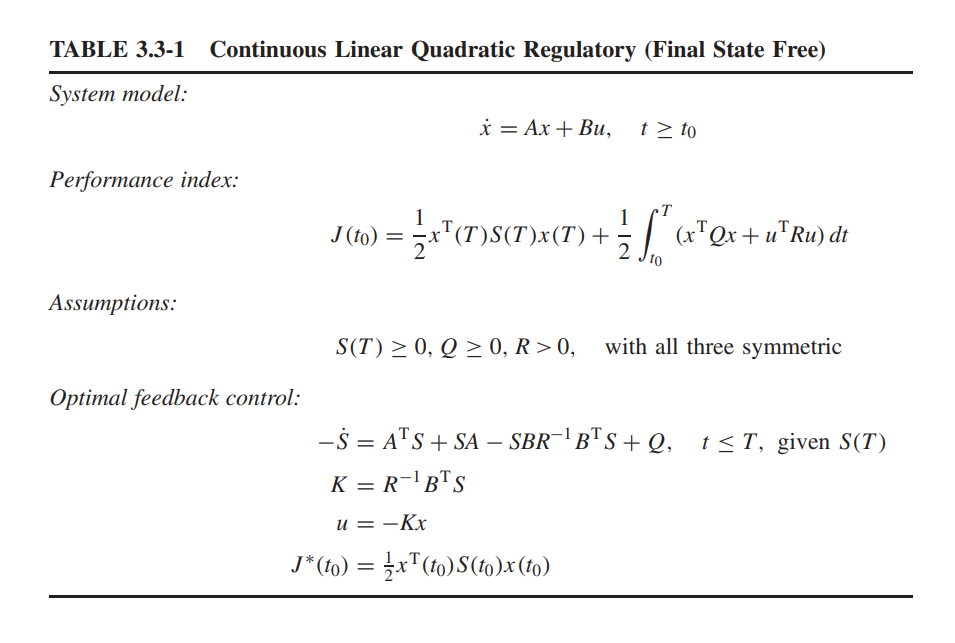

#### Invariant set 

% Define the matrix P
P = [282.26, 81.23; 81.23, 27.38];

% Values for gamma
gamma_values = [1, 2, 3]; % Example values for gamma
colors = ['b', 'm', 'c']; % Colors for different gamma values

% Create a grid of points
x1 = linspace(-1, 1, 100);
x2 = linspace(-1, 1, 100);
[X1, X2] = meshgrid(x1, x2);

% Evaluate the quadratic form x^T P x for each point
QF = P(1,1)*X1.^2 + 2*P(1,2)*X1.*X2 + P(2,2)*X2.^2;

% Create a figure
figure;
hold on;

% Initialize an array to store plot handles
handles = [];

% Plot the feasible region for each value of gamma
for i = 1:length(gamma_values)
    gamma = gamma_values(i);
    % Determine the region where gamma - x^T P x >= 0
    Region = (gamma - QF >= 0);
    
    % Contour plot for the region boundary without filling
    contour(X1, X2, Region, [0.5 0.5], 'LineColor', 'none');
    
    % Contour plot for the boundary with specific color
    [~, h] = contour(X1, X2, QF, [gamma gamma], 'LineColor', colors(i), 'LineWidth', 2);
    handles = [handles, h]; % Store the handle for the legend
end

% Plot the feasible set for states
theta_max = 0.3; % Example value for maximum angle (rad)
theta_dot_max = 0.6; % Example value for maximum angular velocity (rad/s)
% Define the rectangle for feasible set
feasible_x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
feasible_x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
% Fill the feasible set with green color and some transparency
fill(feasible_x1, feasible_x2, 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'g');

% Add text "FS" to the center of the green area
text(0, 0, 'FS', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12, 'Color', 'k');

% Labels and title
title('Feasible Region for Different Values of $\gamma$', 'Interpreter', 'latex');
xlabel('$x_1$', 'Interpreter', 'latex');
ylabel('$x_2$', 'Interpreter', 'latex');

% Add more ticks to the x-axis
xticks(-1:0.2:1);

% Add a legend with only the desired entries
legend(handles, {'\gamma = 1', '\gamma = 2', '\gamma = 3'}, 'Location', 'northeast');

% Grid settings
grid on;
hold off;


% Add a legend with only the desired entries
legend(handles, {'\gamma = 1', '\gamma = 2', '\gamma = 3'}, 'Location', 'northeast');

% Grid settings
grid on;
hold off;

% Define the matrix P
P = [282.26, 81.23; 81.23, 27.38];

% Create a grid of points
theta = linspace(-1, 1, 100);
theta_dot = linspace(-1, 1, 100);
[Theta, Theta_dot] = meshgrid(theta, theta_dot);

% Evaluate the quadratic form QF for each point
QF = P(1,1)*Theta.^2 + 2*P(1,2)*Theta.*Theta_dot + P(2,2)*Theta_dot.^2;

% Create a 3D mesh plot
figure;
mesh(Theta, Theta_dot, QF);
colormap('jet'); % Change the color map from blue to red
colorbar;

% Labels and title
title('3D Plot of Quadratic Form $QF = x^T P x, P=[282.26, 81.23; 81.23, 27.38]$', 'Interpreter', 'latex');
xlabel('$\theta$', 'Interpreter', 'latex');
ylabel('$\dot{\theta}$', 'Interpreter', 'latex');
zlabel('$QF$', 'Interpreter', 'latex');

% Grid settings
grid on;
hold off;

% System parameters
g = 9.81; % gravity (m/s^2)
l = 1.0;  % length of pendulum (m)
m = 1.0;  % mass of pendulum (kg)

% System dynamics
A = [0 1; g/l 0];
B = [0; 1/(m*l^2)];
[n, m] = size(B);

% Define different values of q
q_values = [1, 10, 25, 50];
colors = ['b', 'r', 'g', 'm']; % Colors for different q values
R = eye(m); % Define R

% Create a grid of points
theta = linspace(-1, 1, 100);
theta_dot = linspace(-1, 1, 100);
[Theta, Theta_dot] = meshgrid(theta, theta_dot);

% Create the figure
figure;

% First subplot: theta vs. QF
subplot(1, 2, 1);
hold on;
for i = 1:length(q_values)
    q = q_values(i);
    Q = q * eye(n);
    
    % LQR solution
    [K, Solution, Poles] = lqr(A, B, Q, R);
    
    % Define the matrix P
    P = Solution;
    
    % Evaluate the quadratic form QF for each point
    QF = P(1,1)*Theta.^2 + 2*P(1,2)*Theta.*Theta_dot + P(2,2)*Theta_dot.^2;
    
    % Plot theta vs. QF
    plot(theta, QF(:, 50), 'Color', colors(i), 'DisplayName', ['$q = ', num2str(q), '$']);
end
title('Plot of Quadratic Form $QF$ vs. $\theta$', 'Interpreter', 'latex');
xlabel('$\theta$', 'Interpreter', 'latex');
ylabel('$QF$', 'Interpreter', 'latex');
legend('show', 'Interpreter', 'latex');
grid on;
hold off;

% Second subplot: theta_dot vs. QF
subplot(1, 2, 2);
hold on;
for i = 1:length(q_values)
    q = q_values(i);
    Q = q * eye(n);
    
    % LQR solution
    [K, Solution, Poles] = lqr(A, B, Q, R);
    
    % Define the matrix P
    P = Solution;
    
    % Evaluate the quadratic form QF for each point
    QF = P(1,1)*Theta.^2 + 2*P(1,2)*Theta.*Theta_dot + P(2,2)*Theta_dot.^2;
    
    % Plot theta_dot vs. QF
    plot(theta_dot, QF(50, :), 'Color', colors(i), 'DisplayName', ['$q = ', num2str(q), '$']);
end
title('Plot of Quadratic Form $QF$ vs. $\dot{\theta}$', 'Interpreter', 'latex');
xlabel('$\dot{\theta}$', 'Interpreter', 'latex');
ylabel('$QF$', 'Interpreter', 'latex');
legend('show', 'Interpreter', 'latex');
grid on;
hold off;

% System parameters
g = 10; % gravity (m/s^2)
l = 1.0;  % length of pendulum (m)
m = 2.0;  % mass of pendulum (kg)

% System dynamics
A = [0 1; g/l 0];
B = [0; 1/(m*l^2)];

% LQR solution
[n, m] = size(B);
q = 25; % Example value for Q
Q = q * eye(n);
R = eye(m);

[Solution,K,poles] = icare(A,B,Q,R,[],[],[]);


#### Nonlinear Programming 

import casadi.*

% Define the optimization variable
x = SX.sym('x', 2, 1); % Assuming x is a 2-dimensional vector

% Define the given matrices and constants
Q = 25 * eye(2); % State cost
R = 1; % Input cost
K = [40.62, 13.69];
P = [282.26, 81.23; 81.23, 27.38];

% Define gamma as a variable
gamma = SX.sym('gamma');

% Define the constraint function
constraint = gamma - x' * P * x;

% Define the functions f(x) and g(x) based on your problem
g = 10; % gravitational constant in m/s^2
l = 1.0; % length in meters
m = 2.0; % mass in kg

f_x = [x(2); g/l * sin(x(1))];
g_x = [0; 1/(m*l^2)];

% Ensure all terms are SX type
f_x = SX(f_x);
g_x = SX(g_x);

% Define the input constraints
u = -K * x;
input_constraint = u - 3; % Maximum torque constraint

% Define state constraints
state_constraints = [abs(x(1)) - 0.3; abs(x(2)) - 0.6];

% Define the function to be maximized
objective = -2 * x' * P * (f_x - g_x * K * x);

% Set up the NLP problem with state and input constraints
nlp = struct('x', [x; gamma], 'f', objective, 'g', [constraint; input_constraint; state_constraints]);

% Create the solver
opts = struct('ipopt', struct('print_level', 0, 'tol', 1e-6));
solver = nlpsol('solver', 'ipopt', nlp, opts);

% Define initial guess and bounds
x0 = [0; 0; 0.5]; % Initial guess for x and gamma  Very sensetive
lbg = [-inf; -inf; -inf; 0]; % Lower bound on constraints
ubg = [inf; 0; 0; 0]; % Upper bound on constraints

% Solve the problem
sol = solver('x0', x0, 'lbg', lbg, 'ubg', ubg);

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)         9
       nlp_g  |        0 (       0)        0 (       0)         9
  nlp_grad_f  |   1.00ms (111.11us)   1.02ms (113.67us)         9
  nlp_hess_l  |        0 (       0)        0 (       0)         7
   nlp_jac_g  |        0 (       0)        0 (       0)         9
       total  |   1.61 s (  1.61 s)   1.61 s (  1.61 s)         1



% Extract the solution
x_opt = full(sol.x);
gamma_opt = x_opt(end);

% Display the results
disp(gamma_opt)

    1.3154



% Define the matrix P
P = [282.26, 81.23; 81.23, 27.38];

% Value for gamma
gamma = 1.3154; % Specific value for gamma
color = 'b'; % Color for the plot

% Create a grid of points
x1 = linspace(-1, 1, 100);
x2 = linspace(-1, 1, 100);
[X1, X2] = meshgrid(x1, x2);

% Evaluate the quadratic form x^T P x for each point
QF = P(1,1)*X1.^2 + 2*P(1,2)*X1.*X2 + P(2,2)*X2.^2;

% Create a figure
figure;
hold on;

% Plot the feasible region for gamma
% Determine the region where gamma - x^T P x >= 0
Region = (gamma - QF >= 0);

% Contour plot for the region boundary without filling
contour(X1, X2, Region, [0.5 0.5], 'LineColor', 'none');

% Contour plot for the boundary with specific color
[~, h] = contour(X1, X2, QF, [gamma gamma], 'LineColor', color, 'LineWidth', 2);

% Plot the feasible set for states
theta_max = 0.3; % Maximum angle (rad)
theta_dot_max = 0.6; % Maximum angular velocity (rad/s)
% Define the rectangle for feasible set
feasible_x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
feasible_x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
% Fill the feasible set with green color and some transparency
fill(feasible_x1, feasible_x2, 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'g');

% Add text "FS" to the center of the green area
text(0, 0, 'FS', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12, 'Color', 'k');

% Labels and title
title('Feasible Region for $\gamma = 1.3154$', 'Interpreter', 'latex');
xlabel('$x_1$', 'Interpreter', 'latex');
ylabel('$x_2$', 'Interpreter', 'latex');

% Add more ticks to the x-axis
xticks(-1:0.2:1);

% Add a legend with only the desired entry
legend(h, {'\gamma = 1.3154'}, 'Location', 'northeast');

% Grid settings
grid on;
hold off;

#### Closed-Loop 

% System parameters
m = 2.0; % mass (kg)
l = 1.0; % length (m)
g = 10; % gravitational constant (m/s^2)
K = [40.62, 13.69]; % Feedback gain matrix
P = [282.26, 81.23; 81.23, 27.38]; % Positive-definite matrix
gamma = 1.3154; % Given gamma value

% Desired control input function
u_des = @(t, x) (t < 2) * 3 + (t >= 2 & t < 4) * (-3) + (t >= 4 & t < 6) * 3 + ...
    (t >= 6) * (m * l^2 * (-g/l * sin(x(1)) - [1.5, 1.5] * x));

% Initial state
x0 = [0.1; 0.0]; % Initial state [theta, theta_dot]

% Simulation time
tspan = [0 10]; % Time span for simulation

% Controller function
controller = @(t, x) (norm(u_des(t, x)) > 3 || (x' * P * x >= gamma)) * (-K * x) + ...
                      ~(norm(u_des(t, x)) > 3 || (x' * P * x >= gamma)) * u_des(t, x);

% System dynamics function
dynamics = @(t, x) [x(2); (g/l) * sin(x(1)) + controller(t, x) / (m * l^2)];

% Solve the system using ODE solver
[t, x] = ode45(dynamics, tspan, x0);

% Control input over time
u = arrayfun(@(i) controller(t(i), x(i,:)'), 1:length(t), 'UniformOutput', false);
u = cell2mat(u');

% Plot the state and control input versus time
figure;
subplot(3, 1, 1);
plot(t, x(:, 1), 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('\theta (rad)');
title('State \theta versus Time');
grid on;

subplot(3, 1, 2);
plot(t, x(:, 2), 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('\dot{\theta} (rad/s)');
title('State \dot{\theta} versus Time');
grid on;

subplot(3, 1, 3);
plot(t, u, 'k', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Control Input u (N.m)');
title('Control Input versus Time');
grid on;


% Define the matrix P
P = [282.26, 81.23; 81.23, 27.38];

% Value for gamma
gamma = 1.3154; % Specific value for gamma
color = 'b'; % Color for the plot

% Create a grid of points
x1 = linspace(-1, 1, 100);
x2 = linspace(-1, 1, 100);
[X1, X2] = meshgrid(x1, x2);

% Evaluate the quadratic form x^T P x for each point
QF = P(1,1)*X1.^2 + 2*P(1,2)*X1.*X2 + P(2,2)*X2.^2;

% Create a figure
figure;
hold on;

% Plot the feasible region for gamma
% Determine the region where gamma - x^T P x >= 0
Region = (gamma - QF >= 0);

% Contour plot for the region boundary without filling
contour(X1, X2, Region, [0.5 0.5], 'LineColor', 'none');

% Contour plot for the boundary with specific color
[~, h] = contour(X1, X2, QF, [gamma gamma], 'LineColor', color, 'LineWidth', 2);

% Plot the feasible set for states
theta_max = 0.3; % Maximum angle (rad)
theta_dot_max = 0.6; % Maximum angular velocity (rad/s)
% Define the rectangle for feasible set
feasible_x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
feasible_x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
% Fill the feasible set with green color and some transparency
fill(feasible_x1, feasible_x2, 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'g');

% Add text "FS" to the center of the green area
text(0, 0, 'FS', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12, 'Color', 'k');

% Plot the trajectory of the closed-loop system
plot(x(:, 1), x(:, 2), 'r', 'LineWidth', 2);

% Labels and title
title('Feasible Region for $\gamma = 1.3154$ and Closed-loop Trajectory', 'Interpreter', 'latex');
xlabel('$x_1$', 'Interpreter', 'latex');
ylabel('$x_2$', 'Interpreter', 'latex');

% Add more ticks to the x-axis
xticks(-1:0.2:1);

% Add a legend with only the desired entry
legend([h, plot(NaN, NaN, 'r')], {'\gamma = 1.3154', 'Closed-loop Trajectory'}, 'Location', 'northeast');

% Grid settings
grid on;
hold off;

## Functions

function dxdt = pendulum_dynamics(t, x, g, l, m, control_input)
    theta = x(1);
    theta_dot = x(2);
    % Pendulum Dynamics Function
    % Calculate control input
    u = control_input(t, x);
    
    % System dynamics
    theta_ddot = (g/l) * sin(theta) + (1/(m*l^2)) * u;
    
    % Return the state derivatives
    dxdt = [theta_dot; theta_ddot];
end

function u = control_input(t, x, g, l, m)
    if t >= 0 && t < 2
        u = 3;
    elseif t >= 2 && t < 4
        u = -3;
    elseif t >= 4 && t < 6
        u = 3;
    else
        x1 = x(1);
        x2 = x(2);
        u = m * l^2 * ((-g/l)*sin(x1) - [1.5, 1.5] * [x1; x2]);
    end
end